clear all, close all, clc

% Atibuindo valores das constantes
Ka = 20;
Kb = 0.5;
Ki = 0.5;
Kr = 0.318;

%Tm =

Jm = 0.02;
Jg = 1;
Jl = 1.5;

%Vb = 
%theta_m = 

Bm = 0.01;
Bl = 1;
Ra = 8; 
La = 0.002;

n1 = 1;
n2 = 10;
n3 = 1;
n4 = 1;

% Equacionamento
n = (n1*n3)/(n2*n4);

Jeq = Jm + Jg + n^2*Jl

Jeq = 1.0350

Beq = Bm + n^2*Bl

Beq = 0.0200


% Item (a)
% Funcao transferencia
a = Kr*Ka*Ki*n;
b = La*Jeq;
c = La*Beq + 2*Ra*Jeq;
d = 2*Ra*Beq + Ki*Kb;
e = Kr*Ka*Ki;

f = n*Ki;
g = La*Jeq;
h = La*Beq + 2*Ra*Jeq;
i = 2*Ra*Beq;
j = Ki*Kb;

num=[a]

num = 0.3180

d1=[b c d e]

d1 =     0.0021   16.5600    0.5700    3.1800


G1=tf(num,d1)


G1 =
 
                   0.318
  ---------------------------------------
  0.00207 s^3 + 16.56 s^2 + 0.57 s + 3.18
 
Continuous-time transfer function.




num2=[f]

num2 = 0.0500

d2=[g h i j]

d2 =     0.0021   16.5600    0.3200    0.2500


G2 = tf(num2,d2)


G2 =
 
                   0.05
  ---------------------------------------
  0.00207 s^3 + 16.56 s^2 + 0.32 s + 0.25
 
Continuous-time transfer function.



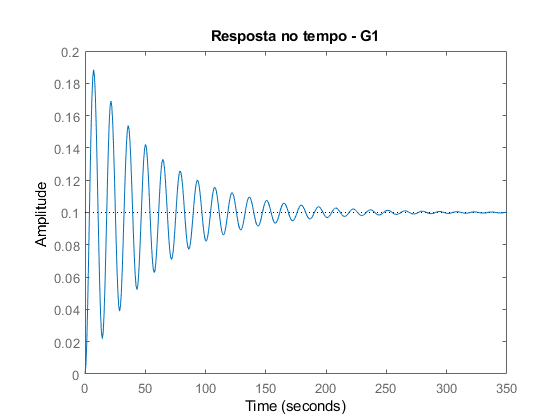


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Item (b) 
% Fazer mapa de estado (ia, theta_m, theta_m')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Item (c) 
% substituir valores no mapa de estado

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Item (d) 
%Resposta temporal
figure
step(G1)
title('Resposta no tempo - G1')

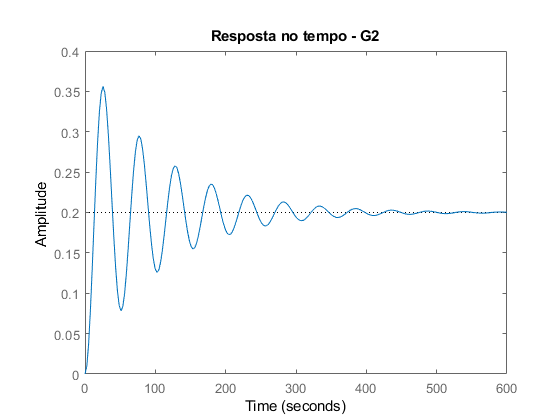


figure
step(G2)
title('Resposta no tempo - G2')


% Criterio de estabilidade e desempenho - Tempo (G1)
zpk(G1)


ans =
 
               153.62
  --------------------------------
  (s+8000) (s^2 + 0.0344s + 0.192)
 
Continuous-time zero/pole/gain model.



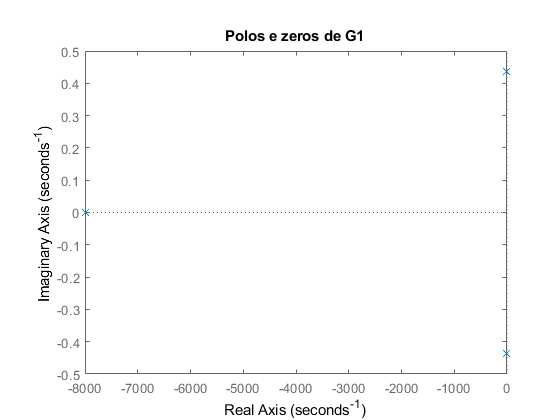

pzmap(G1);
title('Polos e zeros de G1'); % todos polos negativos = Estavel 


% Cálculo do tempo de pico (Tp) para G1
step_info_G1 = stepinfo(G1)  % Obtém informações da resposta ao degrau para G1

step_info_G1 = struct with fields:
        RiseTime: 2.4512
    SettlingTime: 223.2917
     SettlingMin: 0.0219
     SettlingMax: 0.1884
       Overshoot: 88.3915
      Undershoot: 0
            Peak: 0.1884
        PeakTime: 7.1691



Tp_G1 = step_info_G1.PeakTime;  % Obtém o tempo de pico de G1

fprintf('Tempo de pico para G1: %.4f segundos\n', Tp_G1);

Tempo de pico para G1: 7.1691 segundos



% Erro estacionario
erro = 1 - 0.1  % 0.1 = valor quanto tempo tende ao infinito

erro = 0.9000

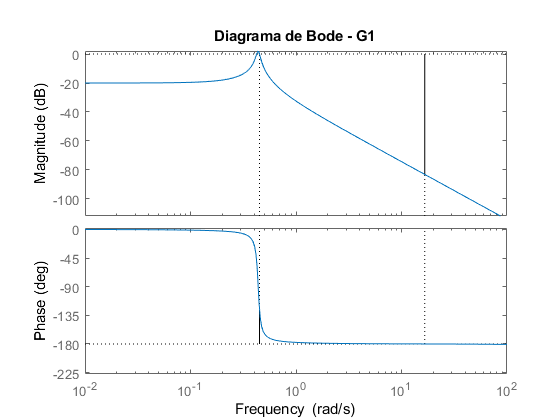



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Item (e) 
%Resposta em frequencia
figure
margin(G1)
title('Diagrama de Bode - G1')

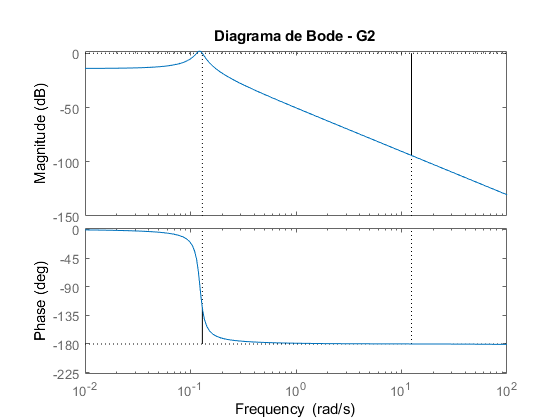


figure
margin(G2)
title('Diagrama de Bode - G2')


% Criterio de estabilidade e desempenho - Frequência (G1)

% Nyquist
zpk(G1)


ans =
 
               153.62
  --------------------------------
  (s+8000) (s^2 + 0.0344s + 0.192)
 
Continuous-time zero/pole/gain model.



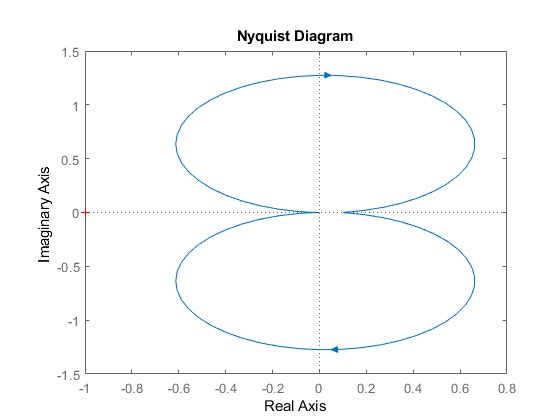

figure
nyquist(G1) % nao tem voltas em torno de -1 e o ponto vermelho na esta dentro do deseho, logo 0 + 0 = 0 -> Estavel

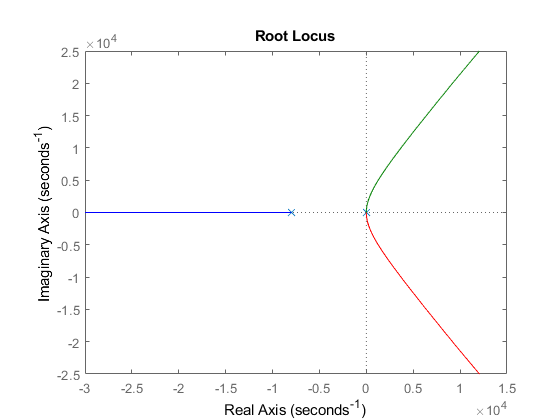



%Análise de Root Locus
figure
rlocus(G1)

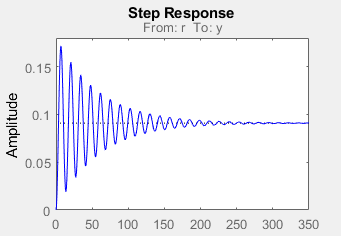

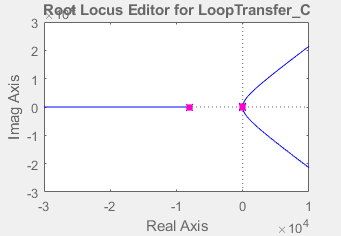

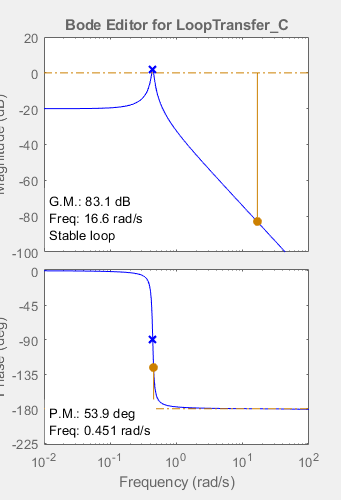

sisotool(G1)


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Item (f) 

%%%% Método Ziegler–Nichols %%%%%
s=tf('s');
P=feedback(G1,1) % Malha fechada


P =
 
                   0.318
  ----------------------------------------
  0.00207 s^3 + 16.56 s^2 + 0.57 s + 3.498
 
Continuous-time transfer function.



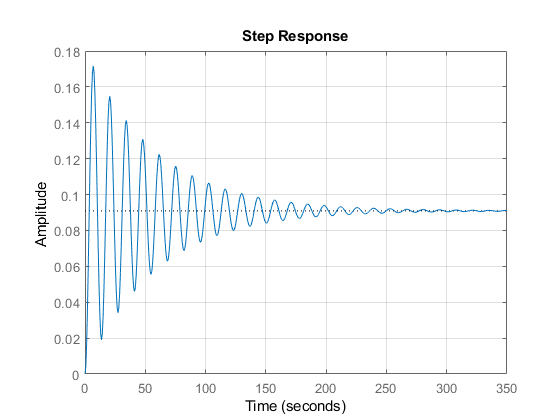


step(P),grid % comportamento temporal malha fechada


%Para calcular os valores de Kp,Kd e Ki devo usar Km e Wm do diagrama de bode 
[Km,Pm,Wm,Wcp] = margin(P) 

Km = 1.4329e+04

Pm = 57.4674

Wm = 16.5941

Wcp = 0.4707


kp=0.6*Km

kp = 8.5972e+03

kd=kp*pi/4/Wm

kd = 406.9074

ki=kp*Wm/pi

ki = 4.5411e+04


K=kd*s+kp+ki/s;

pid(K)


ans =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 8.6e+03, Ki = 4.54e+04, Kd = 407
 
Continuous-time PID controller in parallel form.




LA=K*P;

T=feedback(LA,1); %sistema realimentado de control com PID
damp(T)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -5.70e+00                 1.00e+00       5.70e+00         1.75e-01    
 -1.07e+00 + 1.23e+01i     8.63e-02       1.24e+01         9.36e-01    
 -1.07e+00 - 1.23e+01i     8.63e-02       1.24e+01         9.36e-01    
 -7.99e+03                 1.00e+00       7.99e+03         1.25e-04    


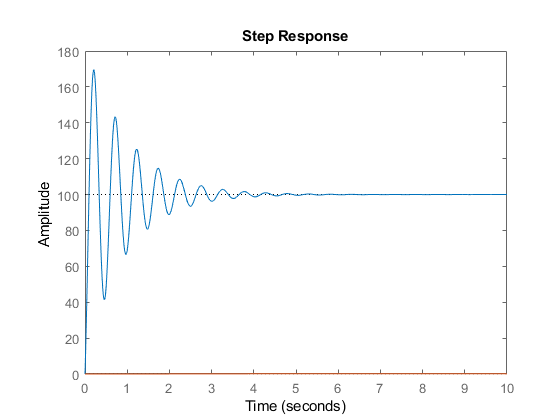

% % Para mostrar as dois respostas coloco 10 vezes T
 figure, step(100*T,10), grid
 hold on 
step(P,10),grid